# A simple test case

A trading strategy with signal input. Sigal as 1 resembles the just hold strategy; and sginal as 0 resembles the just hold cash. You can go to check cost to see how  transaction cost is handled now.

## Input

Time = datetime({'2015-12-18 00:00:00';'2015-12-19 00:00:00';...
    '2015-12-20 00:00:00';'2015-12-21 00:00:00';'2015-12-22 00:00:00'});
assetTT = [0.00022 0.00018 0.00081 -0.00034 0.00045]';
assetTT = timetable(Time, assetTT);
signal = zeros(5,1);
signal(2:4,1) = 1;
signal = timetable(Time, signal);
assetTT

assetTT = 5×1 timetable
            Time            assetTT 
    ____________________    ________

    18-Dec-2015 00:00:00     0.00022
    19-Dec-2015 00:00:00     0.00018
    20-Dec-2015 00:00:00     0.00081
    21-Dec-2015 00:00:00    -0.00034
    22-Dec-2015 00:00:00     0.00045


signal

signal = 5×1 timetable
            Time            signal
    ____________________    ______

    18-Dec-2015 00:00:00      0   
    19-Dec-2015 00:00:00      1   
    20-Dec-2015 00:00:00      1   
    21-Dec-2015 00:00:00      1   
    22-Dec-2015 00:00:00      0   


## Parameters and Strategies

Parameters to configure Backtest object

nAssets = 1;
riskFreeRate = 0.0045/252;
managementFeeRate = 0.02/252;
performanceFeeRate = 0.2/252;
initialPosition = zeros(nAssets, 1)/nAssets;

% you can pick varying value to see the impact of cost for trainedClassifier. 
% changing it to 0.01 will lead to close to zero equity curve for trainedClassifier.
cost_ratio = 0.002; 
costAnalyzerFcn = @(deltaMktVal) costAnalyzer(deltaMktVal, cost_ratio);

strats = [backtest.Strategy('justBuy', 4, 1, @(asset, signal, currpwgt) just_buy(asset, signal, currpwgt), ...
    'TransactionCostFcnHandle', costAnalyzerFcn, ...
    'ManagementFeeRate', managementFeeRate, ...
    'PerformanceFeeRate', performanceFeeRate)];

## BACKTEST

backtester = backtest.Backtest(strats, nAssets, 'RiskFreeRate', riskFreeRate, ...
    'InitialMarketValue', 100, 'InitialPosition', initialPosition);

## backtest with asset return series and signal series 

result = run(backtester, assetTT, signal, 'start', 2, 'end', height(signal));  
tSummary = summary(backtester)

tSummary = 11×1 table
                         justBuy  
                       ___________

    TotalRetn           -0.0018144
    AverageTurnover           0.25
    MaxTurnover                  1
    SharpeRatio           -0.60122
    AverageRetn        -0.00045368
    Volatility          0.00078431
    MaxDrawdown          0.0018144
    AverageBuyCost        0.050003
    AverageSellCost              0
    ManagementFee         0.031751
    PerformanceCost     3.9968e-05


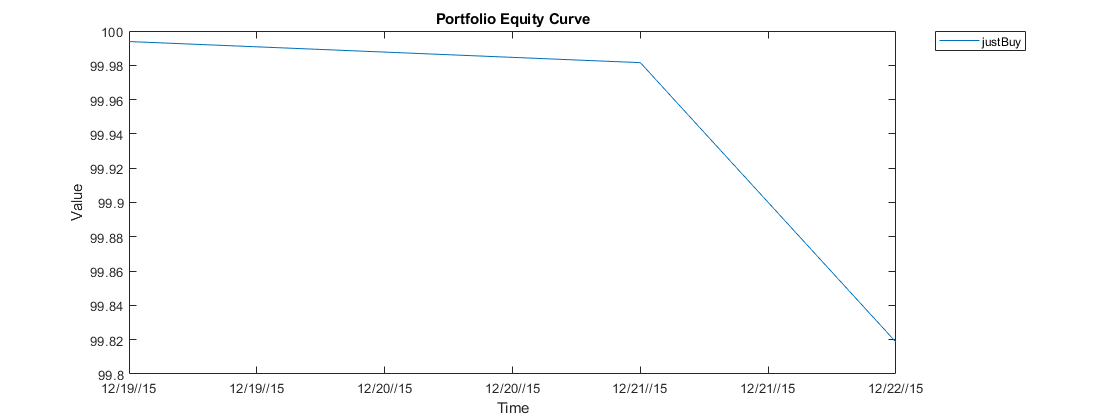

backtester.plotEquityCurve()

## Check cost

Here we can check that the costs. In this version, I kept buy/sell cost aside, instead of offsetting the cash position. And the stored buy/sell costs are used to adjust the portfolio return each day. So since we start with no stock position, for justbuy strategy, we need to purchase on day 1 to get a fully invested postion. Below is the position for each day.

format long
backtester.PositionStructSOD.justBuy

ans = 4×2 timetable
            Time                  Cash              assetTT     
    ____________________    ________________    ________________

    19-Dec-2015 00:00:00                 100                   0
    20-Dec-2015 00:00:00    100.001785714286                   0
    21-Dec-2015 00:00:00    100.003571460459                   0
    22-Dec-2015 00:00:00                   0    100.005357238521


backtester.PwgtStructSOD.justBuy

ans = 4×2 timetable
            Time            Cash    assetTT
    ____________________    ____    _______

    19-Dec-2015 00:00:00     1         0   
    20-Dec-2015 00:00:00     1         0   
    21-Dec-2015 00:00:00     1         0   
    22-Dec-2015 00:00:00     0         1   


backtester.BuyCost shows the buycost accumulated so far. So here, only at day 1, we incur buy cost. Then for following steps, it grows because of risk free rate. I think this makes sense, because we care about the time value of the costs. The portfolio return is adjusted by the this buycost.

backtester.BuyCost

ans = 4×1 timetable
            Time                 justBuy     
    ____________________    _________________

    19-Dec-2015 00:00:00                    0
    20-Dec-2015 00:00:00                    0
    21-Dec-2015 00:00:00                    0
    22-Dec-2015 00:00:00    0.200010714477042


Here we show no sellcost is incurred, which is expected.

backtester.SellCost

ans = 4×1 timetable
            Time            justBuy
    ____________________    _______

    19-Dec-2015 00:00:00       0   
    20-Dec-2015 00:00:00       0   
    21-Dec-2015 00:00:00       0   
    22-Dec-2015 00:00:00       0   


backtester.ManagementCost  % this includes both the performance fee and management fee.

ans = 4×1 timetable
            Time                  justBuy      
    ____________________    ___________________

    19-Dec-2015 00:00:00    0.00793664965986395
    20-Dec-2015 00:00:00     0.0158734410456147
    21-Dec-2015 00:00:00      0.023810374159783
    22-Dec-2015 00:00:00     0.0317508788938527


## local functions

function pwgt = train_classifier(asset, signal)
if signal(end)==1
    pwgt = 1;
else
    pwgt = 0;
end
end

function pwgt = just_buy(asset, signal, currpwgt)
pwgt=1;
end

function [buy, sell] = costAnalyzer(deltaMktVal, ratio)
% costAnalyzer defines the transanction costs, 
% w.r.t the market value changes for each asset before and after buy/sell.
buy = zeros(numel(deltaMktVal), 1);
sell = zeros(numel(deltaMktVal), 1);

buyLevel1 = ratio;
buyLevel2 = ratio;
sellLevel1 = ratio;
sellLevel2 = ratio;

% buy cost
idx = deltaMktVal>0 & deltaMktVal<1e4;
buy(idx) = buyLevel1*deltaMktVal(idx);
idx = deltaMktVal>=1e4;
buy(idx) = buyLevel2*deltaMktVal(idx);
buy = sum(buy);

% sell cost
idx = deltaMktVal<0 & deltaMktVal>-1e3;
sell(idx) = -sellLevel1*deltaMktVal(idx);
idx = deltaMktVal<=-1e3;
sell(idx) = -sellLevel2*deltaMktVal(idx);
sell = sum(sell);
end